# Pilotage des Systèmes Multi-agents

TDs des jours 29 septembre et 02 octobre de 2023

ISN ENSEM - S9

Professeur : Constantin MORARESCU

**étudiant :** Déric Augusto FRANÇA DE SALES

email : *deric-augusto.franca-de-sales6@etu.univ-lorraine.fr*

*Ce document a été généré à partir d'un ficher Live Script dans la version R2020a du logiciel MATLAB. Annexé au document, il y a aussi les fonctions qui ont été crées et utilisées.*

## Introduction

Le pilotage des systèmes multi-agents (SMA) est une discipline fondamentale dans la gestion de groupes d'entités autonomes, appelées agents, qui collaborent pour atteindre des objectifs, qu'ils soient collectifs ou individuels. Cette discipline s'avère essentielle dans de nombreuses applications contemporaines.

L'application majeure réside notamment dans la formation de drones, où les codes de pilotage des SMA permettent aux drones de se déplacer de manière coordonnée, accomplissant des missions de surveillance, de cartographie ou de recherche. De plus, dans le domaine de la robotique collaborative, les SMA sont employés pour orchestrer le travail d'équipes de robots au sein d'environnements industriels ou logistiques, assurant une collaboration efficiente tout en évitant les collisions.

Les TDs démontrent de manière concrète comment le pilotage des systèmes multi-agents peut être mis en œuvre, en expliquant la mise en place de ces techniques.

## Td du jour 29 septembre

### Création de la matrix Laplacienne

Les matrices laplaciennes fournissent une représentation mathématique des interactions locales et de la structure des graphes et des systèmes multi-agents, ce qui facilite leur analyse, leur contrôle et leur compréhension. Elles sont largement utilisées dans ces contextes car elles capturent des informations essentielles pour la modélisation et la gestion de ces systèmes.

Une matrice est considérée comme une matrice laplacienne si elle satisfait certaines propriétés généralement associées aux graphes et aux réseaux. Une matrice laplacienne est dérivée de la matrice d'adjacence d'un graphe et encode des informations sur la structure du graphe. Les proprietés qui definent une matrice comme laplacienne sont les suivantes :

**1. Matrice Carrée** : Une matrice laplacienne doit être carrée, ce qui signifie qu'elle a le même nombre de lignes et de colonnes.

**2. Symétrie** : La matrice laplacienne doit être symétrique. En d'autres termes, si L est la matrice laplacienne, alors L doit être égale à sa transposée, L^T.

**3. Entrées Diagonales** : Les entrées diagonales de la matrice laplacienne doivent satisfaire les conditions suivantes :

- Chaque entrée diagonale (c'est-à-dire, L[i][i]) est égale au degré (nombre d'arêtes connectées à) le sommet correspondant dans le graphe.

- Chaque entrée diagonale est non négative.

- La somme de chaque ligne (en excluant l'élément diagonal) doit être non positive.

**4. Entrées Hors-Diagonale** : Les entrées hors-diagonale (c'est-à-dire, L[i][j] où i ≠ j) sont généralement égales à -1 s'il existe une arête entre le sommet i et le sommet j, et 0 sinon. Cependant, il existe des variations des matrices laplaciennes, comme la matrice laplacienne normalisée, qui peuvent avoir des valeurs différentes dans les entrées hors-diagonale.

Pour la génération des matrices laplaciennes, trois fonctions ont été générées. La première, Laplacien(n) utilise des propriétés mathématiques pour s’assurer que la matrice est laplacienne. Elle a été suggérée par le professeur pendant le TD. 

La deuxième façon de générer la matrice laplacienne c'est parmi des fonctions créées qui génèrent une matrice d’adjascence A et une matrice diagonale D basée sur la matrice d’adjascence. En fin de compte, il suffit de soustraire D par A pour générer la matrice laplacienne souhaitée. Le résultat final peut être vérifié avec la fonction isLaplacianMatrix().

clear all; close all; clc;

n = 10; % indique la quantité de noeuds dans le graphe (elements dans le système)

% méthode 1 :
L1 = Laplacien(n)

L1 =      1     0     0     0     0    -1     0     0     0     0
     0     5    -1    -1     0    -1    -1    -1     0     0
     0    -1     3     0     0    -1     0     0    -1     0
     0    -1     0     2     0    -1     0     0     0     0
     0     0     0     0     1     0     0     0    -1     0
    -1    -1    -1    -1     0     7     0    -1    -1    -1
     0    -1     0     0     0     0     2     0     0    -1
     0    -1     0     0     0    -1     0     3     0    -1
     0     0    -1     0    -1    -1     0     0     4    -1
     0     0     0     0     0    -1    -1    -1    -1     4


% méthode 2 :
A = genererA(n); % generer matrice de adjassance 
D = createDmatrix(A); % generer matrice diagonale
L2 = D - A

L2 =      5    -1     0     0     0    -1    -1    -1     0    -1
    -1     4    -1     0     0    -1    -1     0     0     0
     0    -1     6    -1     0    -1    -1     0    -1    -1
     0     0    -1     3    -1    -1     0     0     0     0
     0     0     0    -1     3     0     0    -1     0    -1
    -1    -1    -1    -1     0     5    -1     0     0     0
    -1    -1    -1     0     0    -1     6    -1     0    -1
    -1     0     0     0    -1     0    -1     3     0     0
     0     0    -1     0     0     0     0     0     2    -1
    -1     0    -1     0    -1     0    -1     0    -1     5


Remarque : la matrice d'adjacence d'un graphe est une matrice binaire où chaque élément (i, j) est égal à 1 si un lien existe entre les nœuds i et j, et 0 sinon. Dans un système multi-agents, cela va représenter les connexions directes entre les agents. 

Maintenant, on peut tester si les méthodes ont été efficaces, via la fonction isLaplacianMatrix.

isLaplacianMatrix(L1)

ans = logical
   1


isLaplacianMatrix(L2)

ans = logical
   1


On peut constater que les deux méthodes marchent pour la géneration d'une matrice laplaciene qui representerá un graphe d'un système quelconque. 

Pour analiser le graph de L1 crée, on utilise la fonction graph :

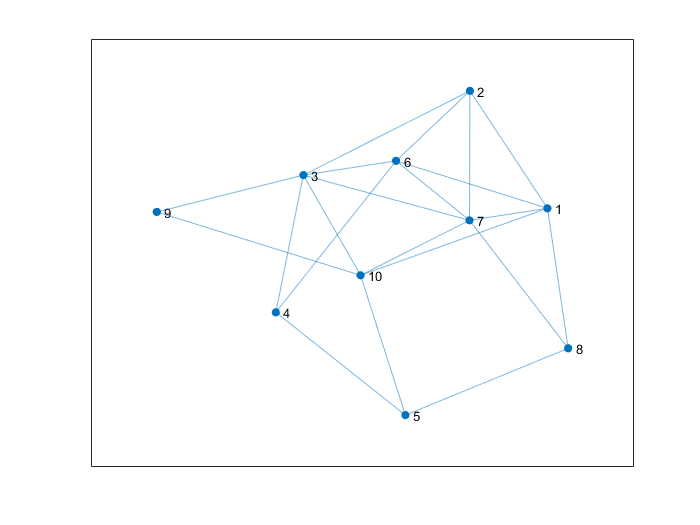

F = graph(A);
plot(F);

### Simulation de l'evolution d'un système multiagent

Après avoir créé la matrice laplacienne L1 qui représente le système, dont le graphe a également été généré, nous sommes en mesure de simuler l'évolution du système en utilisant des conditions initiales aléatoires pour les agents. Le code ci-dessous résout l'équation différentielle ordinaire correspondante et trace la solution temporelle résultante :

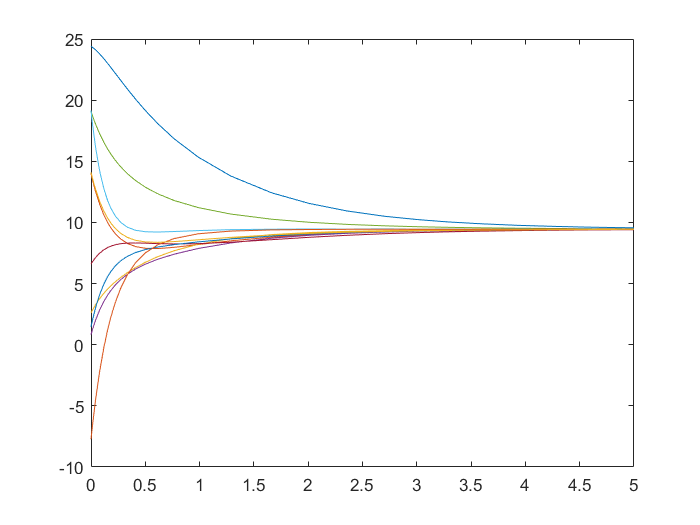

% Générer des conditions initiales aléatoires pour le système
x0 = 30*rand(n,1) - 20*rand(n,1);
y0 = 30*rand(n,1) - 20*rand(n,1);

% Spécifier l'intervalle de temps pour la résolution de l'EDO
tspan = [0 5];

% Résoudre l'EDO en utilisant ode23 avec la fonction anonyme @(t,x) -L*x
[t,x] = ode23(@(t,x) - L1*x, tspan, x0);

% Tracer la solution en fonction du temps
plot(t, x);

Le graphique illustre la convergence du système vers une solution.

### Evaluer la vitesse de convergence

Maintenant on effectue une simulation de système multi-agent, mesurant sa vitesse de convergence, et comment le système évolue au fil du temps en utilisant des graphiques. Ces graphiques von aider à visualiser la vitesse de convergence du système multi-agent, comparant cette vitesse avec la décroissance exponentielle attendue, suivant l'évolution des états du système au fil des itérations de la méthode itérative. Ils aident à comprendre comment le système se comporte au fil du temps et comment il atteint un état d'équilibre.

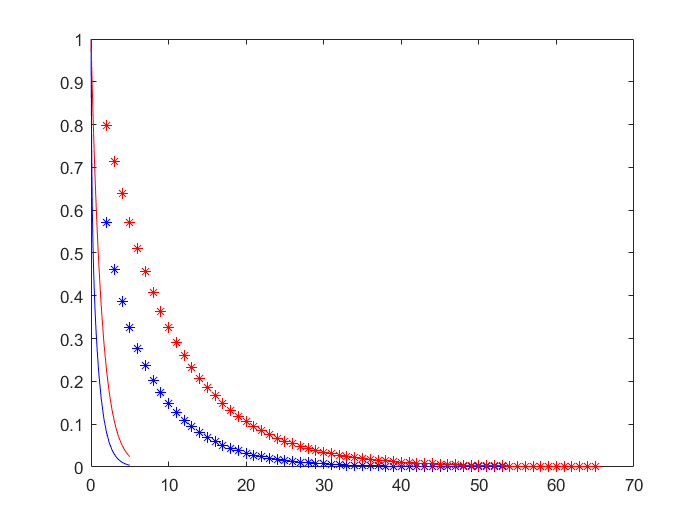

% Calculer la moyenne des conditions initiales des agents
m = mean(x0);

% Calculer les valeurs propres de la matrice laplacienne L1
lambda = eig(L1);

% Boucler à travers chaque instant t et calculer la mesure de la vitesse de convergence
y = zeros(length(t),1);
for i = 1:length(t)
    y(i) = norm(x(i,:)-ones(1,n)*m)/(norm(x0-ones(n,1)*m));

end
% Tracer la mesure de la vitesse de convergence en bleu et la décroissance exponentielle en rouge
plot(t,y,'b',t,exp(-lambda(2)*t),'r');

% Initialiser les conditions initiales des agents
X = [x0];
Y = x0;

% compteur
k = 1;

% Calculer le pas de temps epsilon pour l'itération
epsilon = 1/(max(diag(D)+1));
figure(1)

% Tracer la mesure de la vitesse de convergence en bleu et la décroissance exponentielle en rouge
while (max(Y-ones(n,1)*m)>0.001)
    Y = (eye(n)-epsilon*L1)*Y;
    X = [X,Y];
    k = k+1;
    hold on
    plot(k,norm(Y-ones(1,n)*m)/norm(x0-ones(1,n)*m),'b*',k,(1-lambda(2)*epsilon)^k,'r*');
end
hold off

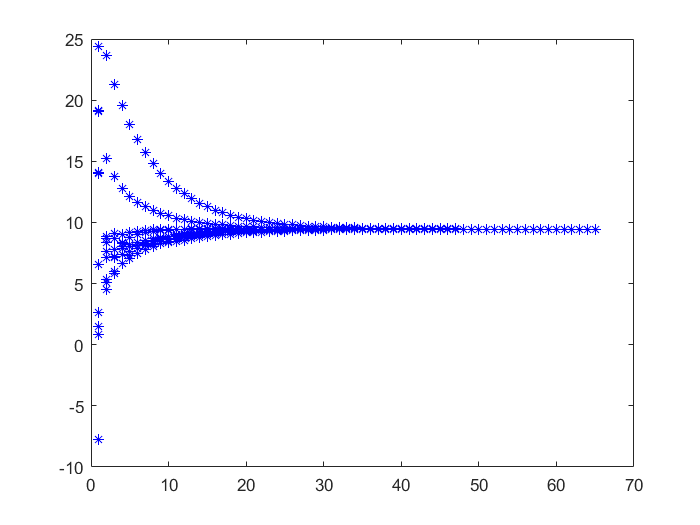

% Créer une deuxième figure et tracer les états du système à chaque itération en bleu
figure(2)
plot(X','*b');

On peut constater que le système converge plus vite qu'une exponentielle a partir des graphes. 

### Tracer une formation

Après avoir généré un système multi-agents et évalué sa vitesse de convergence, on va finalement tracer une formation pour cette système. Ça peut être appliqué par example quand on a des drones dans l'air et on veut qu'ils s'arrangent dans une formation spécifique. Les équations differentielles vont  déterminer comment les drones doivent se déplacer et l'évolution des positions des drones au fil du temps et les affiche graphiquement pour illustrer le processus de convergence vers la formation souhaitée.

Le code ci-dessous génère une formation de points en cercle, puis simule comment cette formation évolue au fil du temps en utilisant des équations différentielles. Il trace les positions initiales en bleu, les positions intermédiaires en rouge à chaque instant, et les positions finales en vert dans la même figure. La formation de points est basée sur les coordonnées polaires et est déplacée selon l'évolution du système multi-agent :

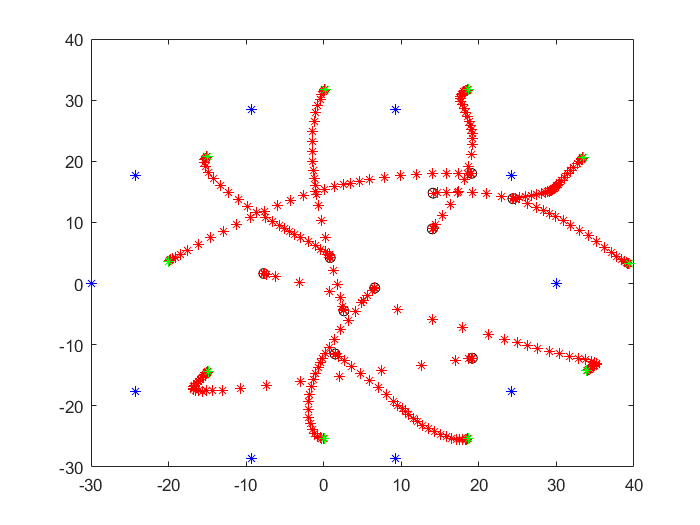

% Définir le rayon de la formation
r = 30;

% Boucle pour calculer les coordonnées des agents dans la formation
f = zeros(n,1);
g = zeros(n,1);
for i = 1:n
    f(i) = r*cos(2*pi*i/n);
    g(i) = r*sin(2*pi*i/n);
end

% Tracer les coordonnées des agents dans la formation en bleu
figure(3)
plot(f,g,'*b');
hold on

% Tracer les coordonnées initiales des agents en noir 
plot(x0, y0, 'ok');

% Calculer les différences entre les positions initiales (x0, y0) et les positions de la formation (f, g)
z0 = x0 - f;
w0 = y0 - g;

% Résoudre l'EDO pour les différences 
[t1,z] = ode23(@(t,z) - L1*z, [0,5], z0);
[t2,w] = ode23(@(t,w) - L1*w, t1, w0);

% Boucle pour mettre à jour les coordonnées X et Y à chaque instant t1
X = z(end,:) + f';
Y = w(end,:) + g';
for i = 1:length(t1)
    X = z(i,:) + f';
    Y = w(i,:) + g';
    % Tracer les coordonnées mises à jour en rouge à chaque instant
    plot(X,Y,'*r');
    hold on
end

% Ttracer les coordonnées finales en vert
figure(3)
plot(X, Y, '*g');

On peut constater selon le graphe que les points noirs ont convergé dans la forme de cercle choisit, correspondent aux point en vert. La position finale des points est donnée en vert.  

## Td du jour 02 octobre

### Simulation de convergence vers une formation équilibrée

Maintenant on va démontrer comment les agents peuvent coopérer et ajuster leurs positions pour atteindre un état d'équilibre commun. Cela peut être applicable dans divers contextes de systèmes multi-agents, tels que la formation de drones, où les drones doivent maintenir une formation prédéfinie.

Le code développé ilustre également le concept de convergence dans les systèmes multi-agents. Il montre comment les interactions entre les agents et les ajustements itératifs peuvent conduire à un état où les agents sont alignés de manière à minimiser les différences entre leurs positions. Cette convergence peut être utile pour atteindre des objectifs spécifiques, comme le maintien d'une formation ou la coordination dans un essaim de robots.

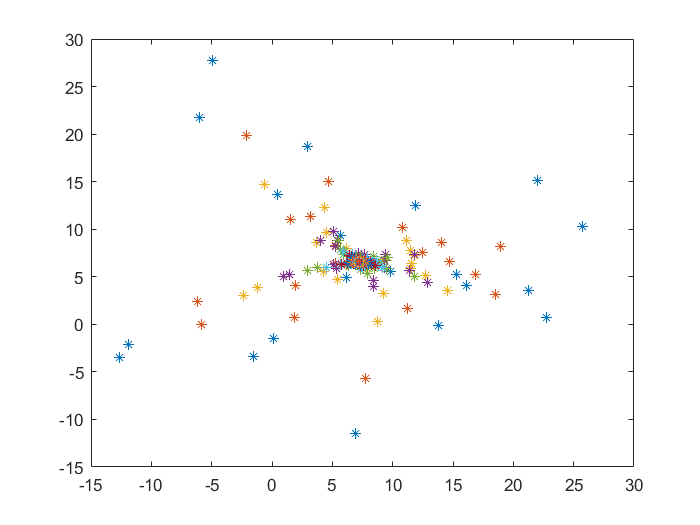

clc; clear all; close all;


% Définit le nombre d'agents dans le système
n = 20;

% Définit le pas de temps epsilon
epsilon = 1 / n;

% Génère des positions initiales aléatoires en x et en y pour les agents
x0 = 30 * rand(n, 1) - 20 * rand(n, 1);
y0 = 30 * rand(n, 1) - 20 * rand(n, 1);

% Initialise les variables x et y avec les positions initiales
x = x0;
y = y0;

% Calcule les moyennes des positions initiales en x et en y
mx = mean(x0);
my = mean(y0);

% Boucle tant que la norme maximale des différences entre x et la moyenne mx
% ou entre y et la moyenne my est supérieure à 10^(-3)
while max(norm(x - ones(n, 1) * mx)) > 10^(-3) || max(norm(y - ones(n, 1) * my)) > 10^(-3)
    
    % Trace les positions actuelles des agents en utilisant des étoiles (*)
    figure(1)
    plot(x, y, '*')
    hold on
    
    % Calcule la matrice laplacienne L pour le nombre d'agents n
    L = Laplacien(n);
    
    % Calcule la matrice de mise à jour p en soustrayant epsilon multiplié par L à la matrice identité
    p = eye(n) - epsilon * L;
    
    % Met à jour les positions des agents en utilisant la matrice p
    x = p * x;
    y = p * y;
end

% Trace les positions finales des agents en utilisant des cercles (o)
plot(x, y, 'o')

% Termine le mode "hold" pour arrêter d'ajouter des éléments au graphique
hold off

### Contrôle de convergence des agents vers des positions désirées sous contraintes de vitesse

Nous allons maintenant simuler le mouvement des agents au sein d'un système multi-agent en suivant des trajectoires pour atteindre des positions désirées. Nous ajusterons constamment la vitesse des agents afin qu'ils convergent vers ces positions tout en veillant à ne pas dépasser une vitesse maximale. La boucle continuera d'exécuter ces opérations tant que la différence maximale en termes de position, que ce soit en x ou en y, entre les agents, sera supérieure à 0.1, et tant que le compteur k sera inférieur à 1000. Enfin, le code tracera les trajectoires des agents dans une figure.

Cette approche peut s'avérer particulièrement utile dans des scénarios où un groupe d'agents doit atteindre des positions spécifiques tout en respectant des contraintes de vitesse. Cette situation est courante dans de nombreux domaines, tels que la robotique, la surveillance, la logistique et la recherche en systèmes multi-agents.

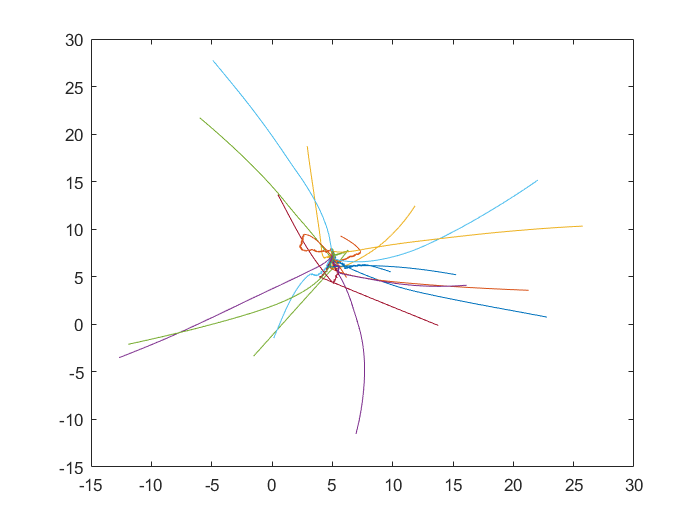


% Initialisation des matrices X et Y avec les positions initiales
X = [x0];
Y = [y0];

% Définition de la vitesse maximale des agents
vmax = 3;

% Initialisation du compteur k à 0
k = 0;

% Boucle tant que la différence maximale en x ou en y entre les positions des agents
% est supérieure à 0.1 et que le compteur k est inférieur à 1000
while (max(X(:,end)) - min(X(:,end)) > 0.1 || max(Y(:,end)) - min(Y(:,end)) > 0.1) && k < 1000
    
    % Calcul des nouvelles positions désirées en utilisant la matrice p
    Xd = p * X(:,end);
    Yd = p * Y(:,end);
    
    % Calcul des angles de direction (theta) pour chaque agent
    theta = atan2(Yd - Y(:,end), Xd - X(:,end));
    
    % Initialisation des vecteurs de vitesse désirée (vd) et de vitesse (v)
    vd = zeros(n, 1);
    v = zeros(n, 1);
    
    % Calcul de la vitesse désirée pour chaque agent
    for i = 1:n
        vd(i) = norm([Xd(i), Yd(i)] - [X(:,end), Y(:,end)]) / epsilon;
        
        % Limite de la vitesse à vmax si elle dépasse vmax
        if vd(i) < vmax
            v(i) = vd(i);
        else
            v(i) = vmax;
        end
    end
    
    % Mise à jour des positions des agents en utilisant la nouvelle vitesse
    X = [X  X(:,end) + epsilon * v .* cos(theta)];
    Y = [Y  Y(:,end) + epsilon * v .* sin(theta)];
    
    % Incrémentation du compteur k
    k = k + 1;
end

% Création d'une nouvelle figure (figure 2)
figure(2)

% Tracé des trajectoires des agents
plot(X', Y')
hold off

### Simulation de déplacement au long de trajectoires parallèles

Nous avons finalement modélisé le déplacement d'un groupe d'agents le long de trajectoires linéaires parallèles au sein d'un système multi-agent. Cette modélisation a permis de démontrer comment les agents ajustent leurs vitesses et leurs positions pour atteindre un état stable où la différence entre leurs vitesses est minimale. Cette simulation s'avère précieuse pour l'étude du comportement de groupes d'agents dans divers contextes, tels que la coordination de robots mobiles ou la planification de trajectoires pour des véhicules autonomes évoluant dans des voies parallèles.

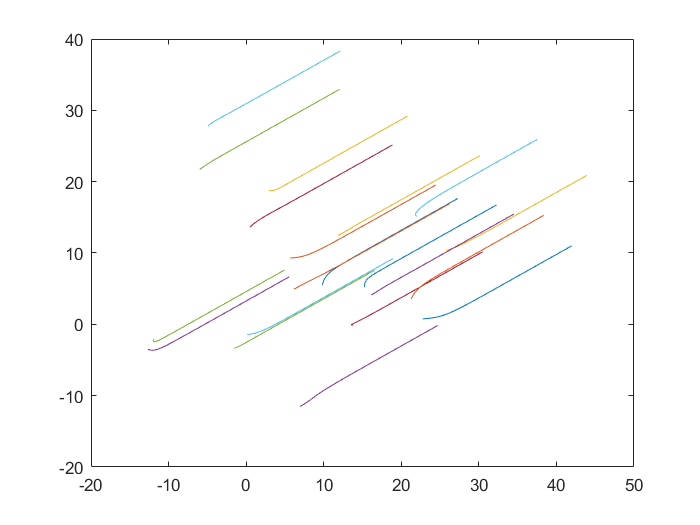

% Création d'une nouvelle figure (figure 3)
figure(3)

% Génération de vitesses initiales aléatoires en x et en y pour les agents
vx0 = 30 * rand(n, 1) - 20 * rand(n, 1);
vy0 = 30 * rand(n, 1) - 20 * rand(n, 1);

% Initialisation des vecteurs de vitesse vx et vy avec les valeurs initiales
vx = vx0;
vy = vy0;

% Initialisation des matrices X et Y avec les positions initiales
X = [x0];
Y = [y0];

% Boucle tant que la différence maximale entre les vitesses en x ou en y
% est supérieure à 10^(-3)
while max(vx) - min(vx) > 10^(-3) || max(vy) - min(vy) > 10^(-3)
    
    % Mise à jour des vitesses en utilisant la matrice p
    vx = p * vx;
    vy = p * vy;
    
    % Mise à jour des positions en ajoutant les variations de positions
    X = [X  X(:, end) + epsilon * vx];
    Y = [Y  Y(:, end) + epsilon * vy];
end

% Tracé des trajectoires des agents
plot(X', Y')